#### CALCULATING NUMBER OF PIXELS FOR IMAGE

cm=imread ('cameraman.tif');
[m,n]=size(cm);
SUM=0;
for i=1:m 
    for j=1:n
        SUM=SUM + cm(i,j);
    end
end
fprintf('NUMBER OF PIXELS IN IMAGE IS %d',SUM);

NUMBER OF PIXELS IN IMAGE IS 255

fprintf ('The Input Image is:');

The Input Image is:

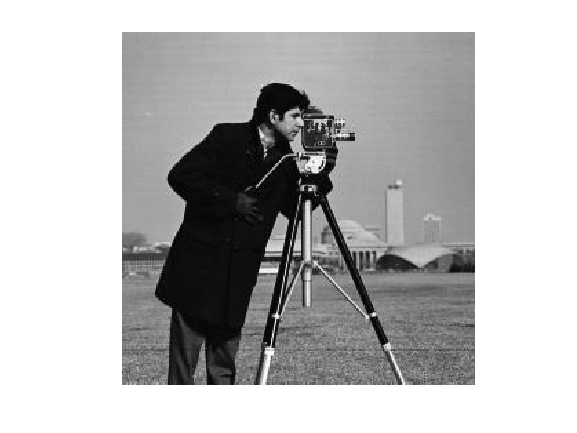

imshow(cm);

#### 1. Program to determine the frequency of given pixel occurring in an image.

pix=8;
count=0;
cm=imread ('cameraman.tif');
[m,n]=size(cm);
for i=1:m
    for j=1:n
        if (cm(i,j)==pix)
            count=count+1;
        end
    end
end
fprintf('FREQUENCY OF %d PIXEL IS %d',pix,count);

FREQUENCY OF 8 PIXEL IS 527

#### 2. Program to calculate the global mean value in a two dimensional matrix M * N.

sum=double(0);
cm=imread ('cameraman.tif');
[m,n]=size(cm);
for i=1:m
    for j=1:n
        sum=sum+double(cm(i,j));
    end
end
fprintf('The global mean of the 2D image is %d',sum/double((m*n)))

The global mean of the 2D image is 1.187179e+02

#### 3. Program to calculate the mean value of every row in a two dimensional matrix M *N.

sum=double(0);
cm=imread ('cameraman.tif');
[m,n]=size(cm);
for i=1:m
    for j=1:n
        sum=sum+double(cm(i,j));
    end
    fprintf('The %d row mean is %d\n',i,sum/n);
    sum=double(0);
end

The 1 row mean is 1.707500e+02
The 2 row mean is 1.709922e+02
The 3 row mean is 1.711523e+02
The 4 row mean is 1.709961e+02
The 5 row mean is 1.707578e+02
The 6 row mean is 1.709023e+02
The 7 row mean is 1.713711e+02
The 8 row mean is 1.718711e+02
The 9 row mean is 1.707422e+02
The 10 row mean is 1.700859e+02
The 11 row mean is 1.700664e+02
The 12 row mean is 1.712188e+02
The 13 row mean is 1.721602e+02
The 14 row mean is 1.717539e+02
The 15 row mean is 1.709648e+02
The 16 row mean is 1.707695e+02
The 17 row mean is 1.706289e+02
The 18 row mean is 1.714727e+02
The 19 row mean is 1.722031e+02
The 20 row mean is 1.719688e+02
The 21 row mean is 1.713086e+02
The 22 row mean is 1.708008e+02
The 23 row mean is 1.707344e+02
The 24 row mean is 1.707539e+02
The 25 row mean is 1.709258e+02
The 26 row mean is 1.715312e+02
The 27 row mean is 1.719453e+02
The 28 row mean is 1.717344e+02
The 29 row mean is 1.715273e+02
The 30 row mean is 1.717070e+02
The 31 row mean is 1.719414e+02
The 32 row mean i

#### 4. Program to determine the frequency of each pixel occurring in a column of an image.

cm=imread ('cameraman.tif');
[m,n]=size(cm);
val=cm(:);
elt=unique(val);
for z=1:length(elt)
    freq=double(0);
    for i=1:m
        for j=1:n
            if(cm(i,j)==elt(z))
                freq=freq+1;
            end
        end
    end
    fprintf('The frequency of %d pixel is %d\n',elt(z),freq);
end

The frequency of 0 pixel is 166
The frequency of 1 pixel is 54
The frequency of 2 pixel is 58
The frequency of 3 pixel is 83
The frequency of 4 pixel is 117
The frequency of 5 pixel is 123
The frequency of 6 pixel is 187
The frequency of 7 pixel is 276
The frequency of 8 pixel is 527
The frequency of 9 pixel is 733
The frequency of 10 pixel is 854
The frequency of 11 pixel is 1016
The frequency of 12 pixel is 1299
The frequency of 13 pixel is 1408
The frequency of 14 pixel is 1641
The frequency of 15 pixel is 1376
The frequency of 16 pixel is 869
The frequency of 17 pixel is 524
The frequency of 18 pixel is 322
The frequency of 19 pixel is 243
The frequency of 20 pixel is 231
The frequency of 21 pixel is 175
The frequency of 22 pixel is 143
The frequency of 23 pixel is 162
The frequency of 24 pixel is 124
The frequency of 25 pixel is 124
The frequency of 26 pixel is 104
The frequency of 27 pixel is 127
The frequency of 28 pixel is 98
The frequency of 29 pixel is 100
The frequency of 30

#### 5. Program to find out total number of pixels which has less than the given intensity.

intensity=8;
count=0;
cm=imread ('cameraman.tif');
[m,n]=size(cm);
for i=1:m
    for j=1:n
        if (cm(i,j)<pix)
            count=count+1;
        end
    end
end
fprintf('NUMBER OF PIXELS LESS THAN %d INTENSITY IS %d',intensity,count);

NUMBER OF PIXELS LESS THAN 8 INTENSITY IS 278

## OPTIONAL

#### Program to determine the frequency of given pixel occurring in a color image.

pix=8;
count=0;
veg=imread ('onion.png');
[m,n]=size(veg);
for i=1:m
    for j=1:n
        if (veg(i,j)==pix)
            count=count+1;
        end
    end
end
fprintf('FREQUENCY OF %d PIXEL IS %d',pix,count);

FREQUENCY OF 8 PIXEL IS 385

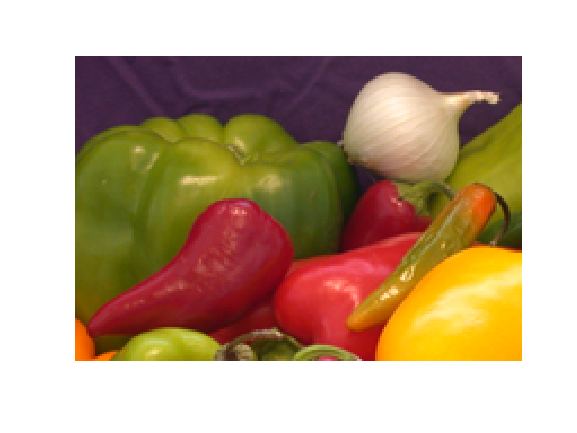

imshow(veg)